# Computational Methods in Physics (PHY4605) - **Data Processing**

## Overview

Data can require preprocessing techniques to ensure accurate, efficient, or meaningful analysis. Data cleaning refers to methods for finding, removing, and replacing bad or missing data. Detecting local extrema and abrupt changes can help to identify significant data trends. Smoothing and detrending are processes for removing noise and polynomial trends from data, while scaling changes the bounds of the data. Other common data processing techniques include detecting local extrema, data grouping and binning.

## **Data Cleaning**

The following exemplifies the use of interpolation to replace `NaN` values in nonuniformly sampled data. Define a vector of nonuniform sample points and evaluate the sine function over the points, then inject `NaN` values into `YData`:

XData = [-4*pi : 0.1 : 0, 0.1 : 0.2 : 4*pi];
YData = sin(XData);
GappedYData = YData;
GappedYData(GappedYData < 0.75 & GappedYData > 0.5) = NaN;

Then plot the gapped data:

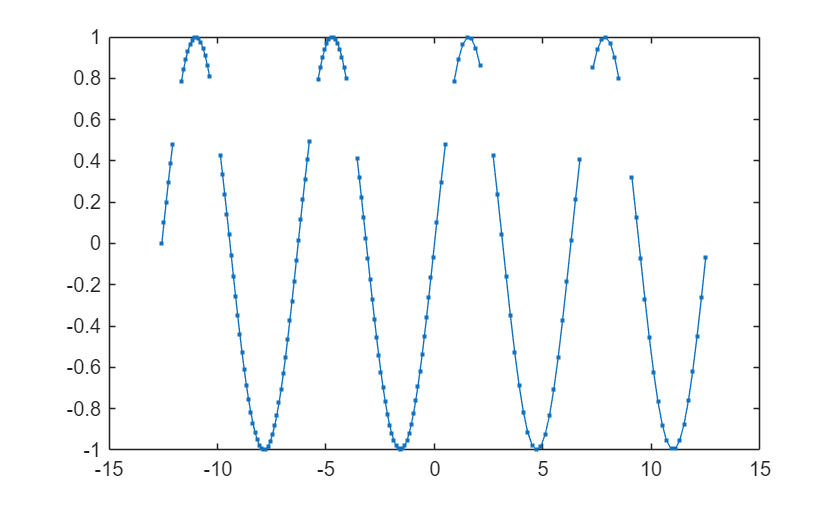

cla
plot(XData, GappedYData, Marker = '.');
hold on

Fill the missing data using linear interpolation, and return the filled vector `FilledYData` and the logical vector . The value 1 (`true`) in entries of `FilledDataIdx` corresponds to the values of `FilledYData` that were filled:

[FilledYData, FilledDataIdx] = fillmissing(GappedYData, 'linear', SamplePoints = XData);

Plot the filled data:

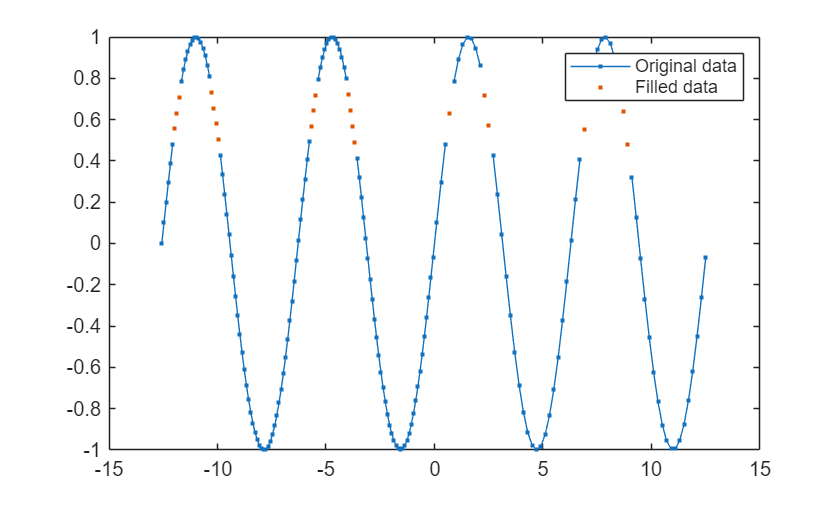

plot(XData(FilledDataIdx), FilledYData(FilledDataIdx), Marker = '.', LineStyle = 'none');
hold off
legend('Original data', 'Filled data');

Using the previous data, inject some extremely high and low values that can be considered outliers; plot the data containing outliers:

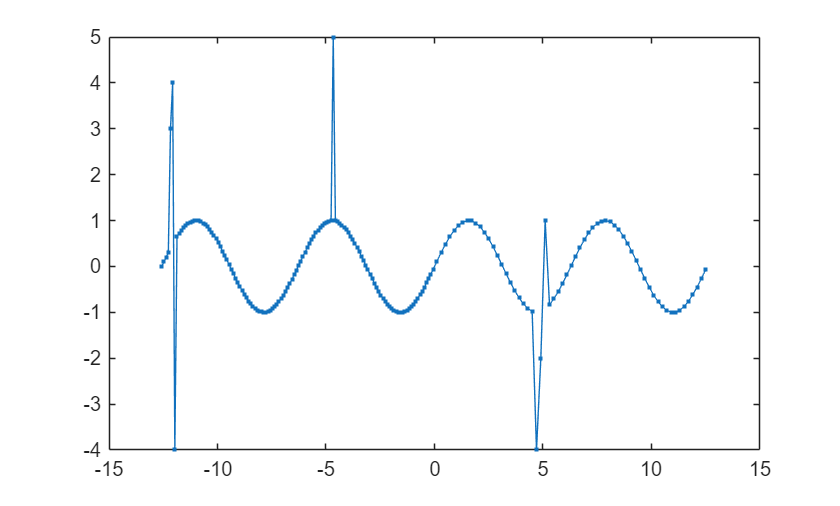

SpikedYData = YData;
SpikedYData([5:7, 80:81, 150:152]) = randi([-5, 5], [1, 8]);
plot(XData, SpikedYData, Marker = '.');

Check whether the outliers can be identified using appropriate `findmethod `like `movmedian`:

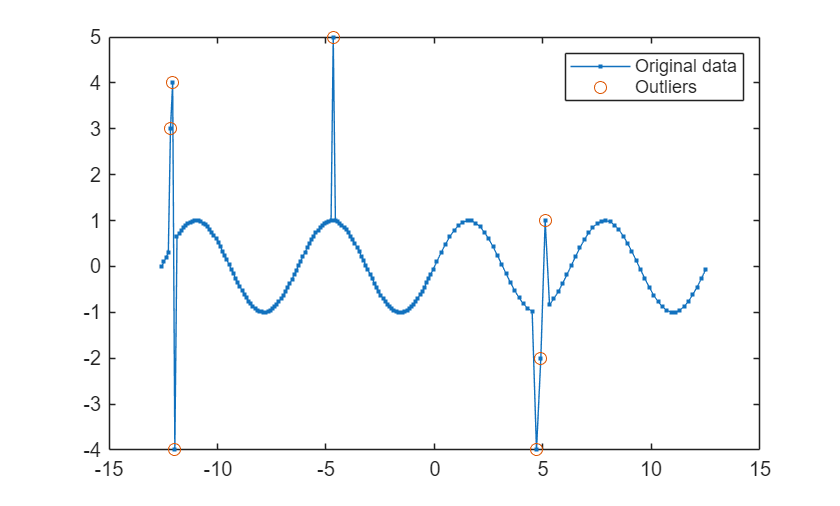

IsOutlier = isoutlier(SpikedYData, 'movmedian', 15);
cla
plot(XData, SpikedYData, Marker = '.');
hold on
plot(XData(IsOutlier), SpikedYData(IsOutlier), Marker = 'o', LineStyle = 'none');
hold off
legend('Original data', 'Outliers');

Then, use `filloutliers` to automatically detect outliers and replace them with interpolated data. Try `linear `and `spline `for `fillmethod`, as well as `movmedian` for `findmethod`:

[CleanedYData, CleanedDataIdx] = filloutliers(SpikedYData, 'spline', 'movmedian', 15, ThresholdFactor = 0.7);

Plot replaced data:

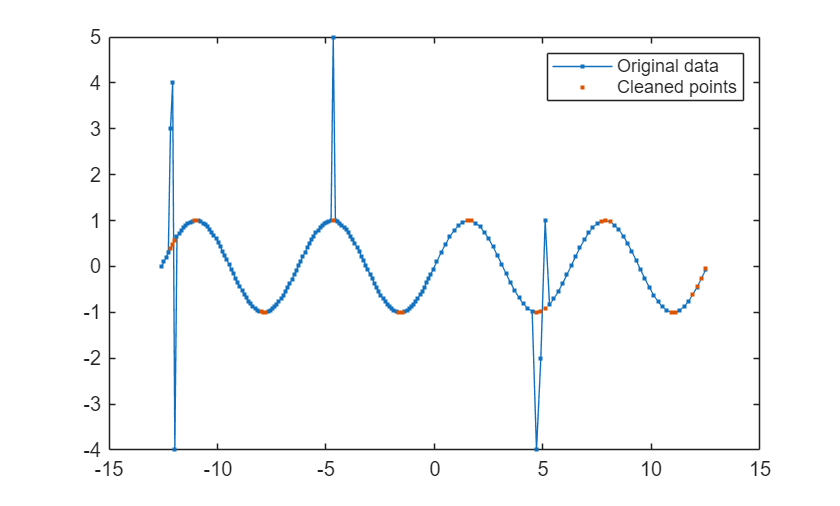

cla
hold on
plot(XData, SpikedYData, Marker = '.');
plot(XData(CleanedDataIdx), CleanedYData(CleanedDataIdx), Marker = '.', LineStyle = 'none');
hold off
legend('Original data', 'Cleaned points');

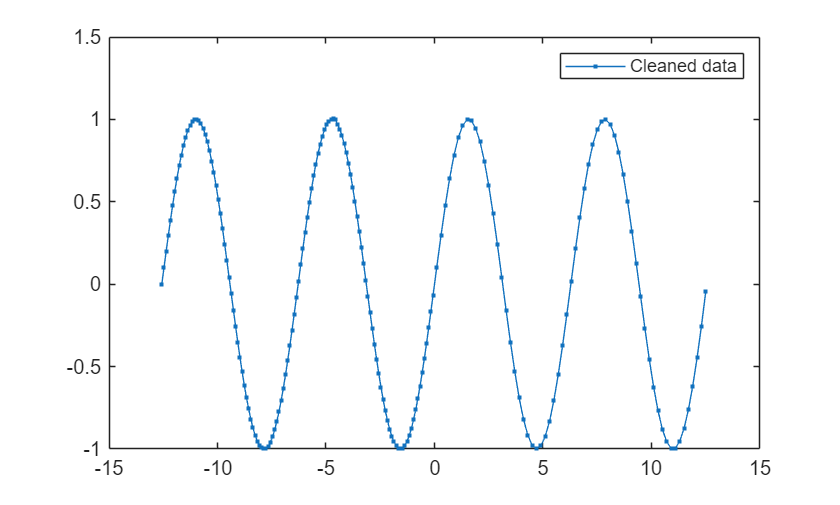

cla
plot(XData, CleanedYData, Marker = '.');
legend('Cleaned data');

The following illustrates how different interpolation ('*gap-filling'*) methods work:

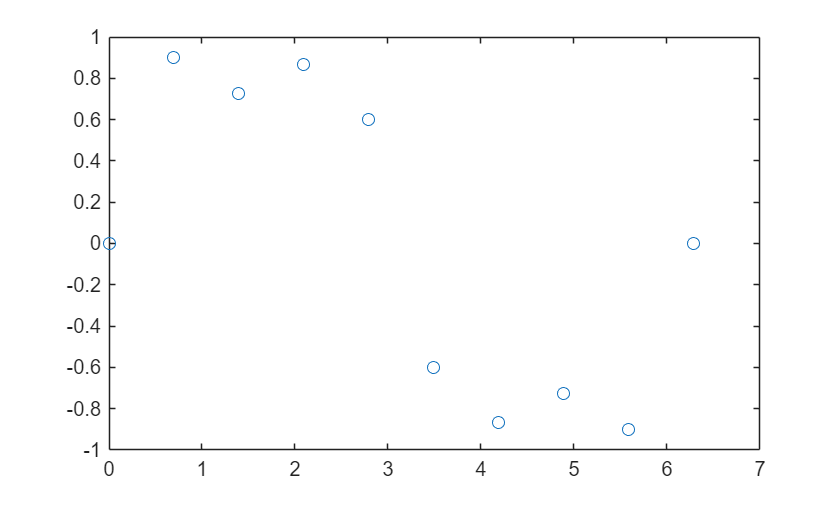

XData = linspace(0, 2*pi, 10);
YData = sin(XData) + 0.3*sin(3*XData);
plot(XData, YData, 'o', LineStyle = 'none');

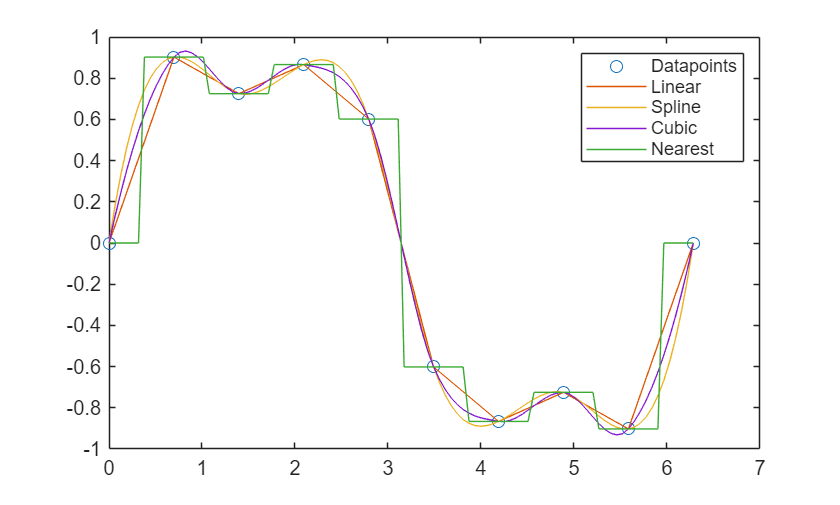

XInterp = linspace(0, 2*pi, 100);
YLinear = interp1(XData, YData, XInterp, 'linear');
YSpline = interp1(XData, YData, XInterp, 'spline');
YCubic = interp1(XData, YData, XInterp, 'cubic');
YNearest = interp1(XData, YData, XInterp, 'nearest');
cla
plot(XData, YData, 'o', LineStyle = 'none');
hold on 
plot(XInterp, YLinear);
plot(XInterp, YSpline);
plot(XInterp, YCubic);
plot(XInterp, YNearest);
hold off
legend('Datapoints', 'Linear', 'Spline', 'Cubic', 'Nearest');

## Data Smoothing

The following demonstrates the process of smoothing noisy data using one of many filters provided by MATLAB. Create a matrix whose rows represent three noisy signals. Smooth the three signals using a moving average, and plot the original and smoothed data:

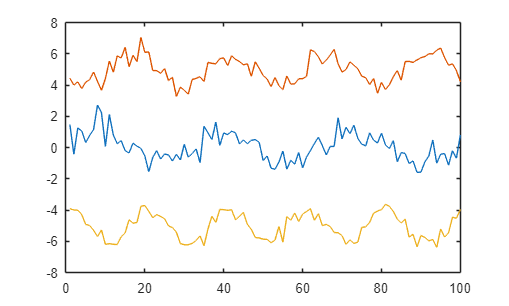

XData = 1 : 100;
Signal1 = cos(2*pi*0.03*XData+2*pi*rand) + 0.5*randn(1,100);
Signal2 = cos(2*pi*0.04*XData+2*pi*rand) + 0.4*randn(1,100) + 5;
Signal3 = cos(2*pi*0.05*XData+2*pi*rand) + 0.3*randn(1,100) - 5;
NoisyYData = [Signal1; Signal2; Signal3]';
plot(NoisyYData, DisplayName = 'Noisy data');

Try different `movmedian `window sizes:

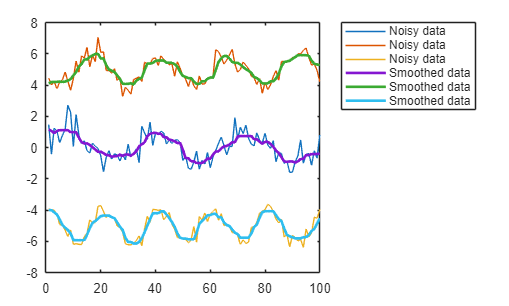

SmoothedYData = smoothdata(NoisyYData, 'movmedian', 8);
cla
plot(NoisyYData, DisplayName = 'Noisy data');
hold on
plot(SmoothedYData, LineWidth = 2, DisplayName = 'Smoothed data');
hold off
legend(Location = 'bestoutside')

## Trend Decomposition

This example shows how to decompose a vector of data into its long-term trend, two seasonal trends, and remainder using singular spectrum analysis. Create a vector of data `MixedSignal` that contains a long-term trend, two seasonal trends with different periods, and a noise component:

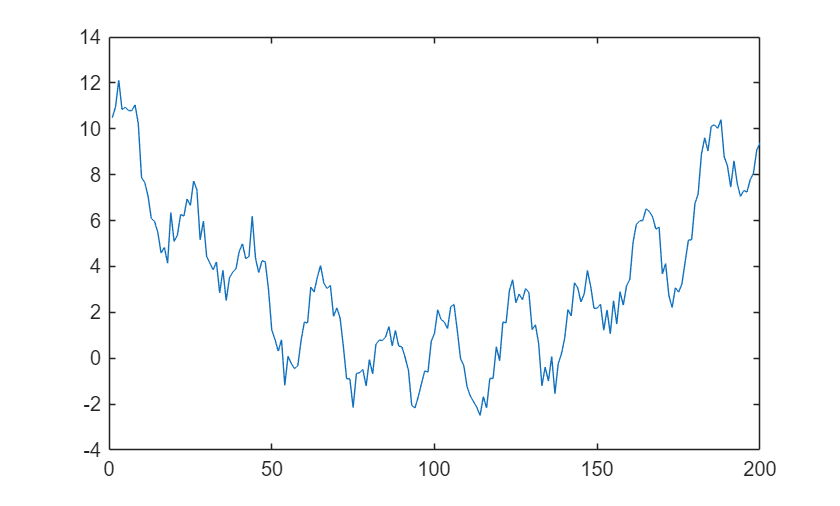

Time = (1 : 200)';
Trend = 0.001 * (Time - 100).^2;
Period1 = 20;
Period2 = 30;
Seasonal1 = 2 * sin(2 * pi * Time / Period1);
Seasonal2 = 0.75 * sin(2 * pi * Time/ Period2);
Noise = 2 * (rand(200, 1) - 0.5);
MixedSignal = Trend + Seasonal1 + Seasonal2 + Noise;
plot(MixedSignal);

Decompose the data using the SSA algorithm. Plot the data, the trends, and the remainder.

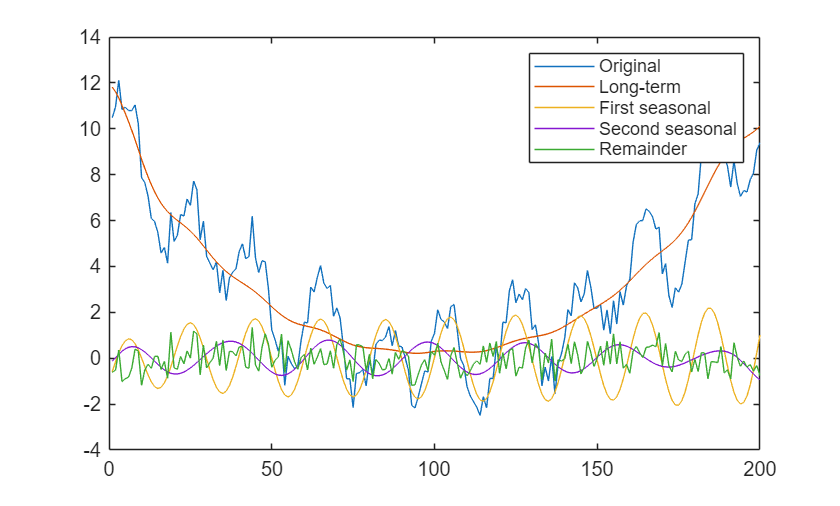

[LongTerm, ShortTerm, Remainder] = trenddecomp(MixedSignal);
plot([MixedSignal, LongTerm, ShortTerm, Remainder]);
legend('Original','Long-term', 'First seasonal','Second seasonal', 'Remainder');

## Data Normalization

The function `normalize` enables users to normalize data in various methods as described below:

- *z*-score - rescales data so that they have a mean of 0 or/and a standard deviation of 1

- 2-norm -  divides each component of a vector by its 2-norm (also called Euclidean norm or length), which is calculated as the square root of the sum of the squares of its components

- Range - Rescales range of data to [0, 1]

- Median IQR - Centers and scales data to have median 0 and interquartile range 1

The following shows an example of scaling a vector by its standard deviation:

Vec = 1 : 5

Vec =      1     2     3     4     5


ScaledVec = normalize(Vec, 'zscore')

ScaledVec =    -1.2649   -0.6325         0    0.6325    1.2649


Scaling the vector so that its range is in the interval [1, 3]:

NormVec = normalize(Vec, 'range', [1, 3])

NormVec =     1.0000    1.5000    2.0000    2.5000    3.0000


### Physics Focus 🔎: Normalization of Meteorological Data

When dealing with time series datasets like meteorological data, it is common to normalize a dataset of a given year before further analysis or processing. Since data from different years might exhibit distinct characteristics, it is therefore crucial to preserve them. To ensure this, we can perform normalization on a dataset while returning the computed parameter values, then reuse the parameters to apply the same normalization to datasets of different years.

Create a timetable with two variables, `Temperature` and `WindSpeed`:

Dates2022 = (datetime(2022, 1, 1) : days(1) : datetime(2022, 12, 31))';
Temperature = randi([15, 35], numel(Dates2022), 1);
WindSpeed = randi([0, 20], numel(Dates2022), 1);
Data2022 = timetable(Temperature, WindSpeed, RowTimes = Dates2022)

Data2022 = 365×2 timetable
       Time        Temperature    WindSpeed
    ___________    ___________    _________

    01-Jan-2022        35             2    
    02-Jan-2022        19             2    
    03-Jan-2022        17             3    
    04-Jan-2022        17             4    
    05-Jan-2022        16             6    
    06-Jan-2022        23             6    
    07-Jan-2022        24             4    
    08-Jan-2022        22             5    
    09-Jan-2022        31            18    
    10-Jan-2022        28            14    
    11-Jan-2022        31            11    
    12-Jan-2022        34             3    
    13-Jan-2022        35        

Then create a second timetable with the same variables, but with the samples taken a year later:

Dates2023 = (datetime(2023, 1, 1) : days(1) : datetime(2023, 12, 31))';
Temperature = randi([10, 40], numel(Dates2023), 1);
WindSpeed = randi([10, 30], numel(Dates2023), 1);
Data2023 = timetable(Temperature, WindSpeed, RowTimes = Dates2023)

Data2023 = 365×2 timetable
       Time        Temperature    WindSpeed
    ___________    ___________    _________

    01-Jan-2023        37            10    
    02-Jan-2023        28            24    
    03-Jan-2023        12            27    
    04-Jan-2023        38            30    
    05-Jan-2023        34            11    
    06-Jan-2023        18            19    
    07-Jan-2023        26            22    
    08-Jan-2023        40            24    
    09-Jan-2023        32            25    
    10-Jan-2023        36            23    
    11-Jan-2023        23            25    
    12-Jan-2023        24            17    
    13-Jan-2023        27        

Plot histograms of temperature and wind speed data for both years to see the difference in data distribution:

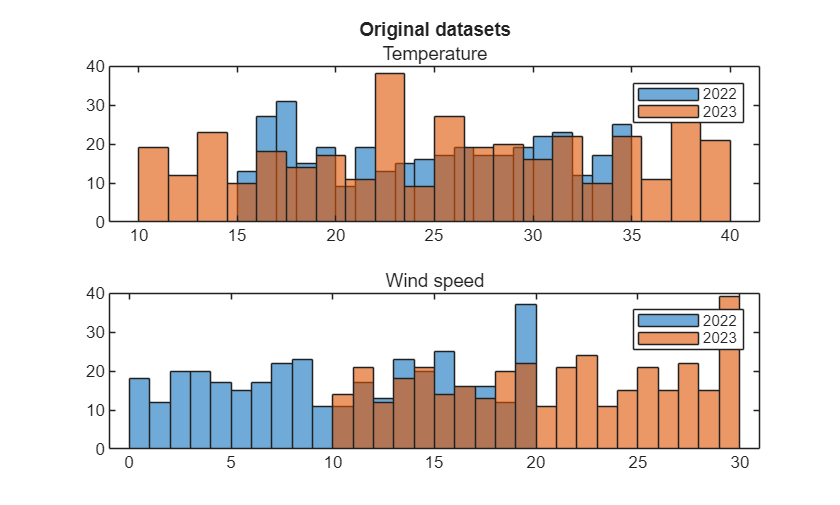

tiledlayout('flow');
nexttile;
histogram(Data2022.Temperature, 20, DisplayName = '2022');
hold on
histogram(Data2023.Temperature, 20, DisplayName = '2023');
hold off
legend
title('Original datasets');
subtitle('Temperature');

nexttile;
histogram(Data2022.WindSpeed, 20, DisplayName = '2022');
hold on
histogram(Data2023.WindSpeed, 20, DisplayName = '2023');
hold off
legend
subtitle('Wind speed');

Normalize the first timetable. Specify three outputs: the normalized table, and also the centering and scaling parameter values that the function uses to perform the normalization:

[NormData2022, CenterValue, ScaleValue] = normalize(Data2022)

NormData2022 = 365×2 timetable
       Time        Temperature    WindSpeed
    ___________    ___________    _________

    01-Jan-2022        1.7214      -1.3313 
    02-Jan-2022      -0.91647      -1.3313 
    03-Jan-2022       -1.2462      -1.1658 
    04-Jan-2022       -1.2462      -1.0004 
    05-Jan-2022       -1.4111     -0.66949 
    06-Jan-2022      -0.25701     -0.66949 
    07-Jan-2022     -0.092144      -1.0004 
    08-Jan-2022      -0.42187     -0.83493 
    09-Jan-2022        1.0619       1.3159 
    10-Jan-2022       0.56732      0.65408 
    11-Jan-2022        1.0619      0.15774 
    12-Jan-2022        1.5565      -1.1658 
    13-Jan-2022        1.7214

CenterValue = 1×2 table
    Temperature    WindSpeed
    ___________    _________

      24.559        10.047  


ScaleValue = 1×2 table
    Temperature    WindSpeed
    ___________    _________

      6.0656        6.0443  


Now normalize the second timetable `Data2023 `using the parameter values from the first normalization. This technique ensures that the data in `Data2023` is centered and scaled in the same manner as `Data2022:`

NormData2023 = normalize(Data2023, Center = CenterValue, Scale = ScaleValue)

NormData2023 = 365×2 timetable
       Time        Temperature    WindSpeed 
    ___________    ___________    __________

    01-Jan-2023        2.0511     -0.0077057
    02-Jan-2023       0.56732         2.3085
    03-Jan-2023       -2.0705         2.8049
    04-Jan-2023         2.216         3.3012
    05-Jan-2023        1.5565        0.15774
    06-Jan-2023       -1.0813         1.4813
    07-Jan-2023       0.23759         1.9776
    08-Jan-2023        2.5457         2.3085
    09-Jan-2023        1.2268          2.474
    10-Jan-2023        1.8862         2.1431
    11-Jan-2023      -0.25701          2.474
    12-Jan-2023     -0.092144         1.1504
    13-Jan-2023

Plot similar histograms for both years after normalizing the datasets:

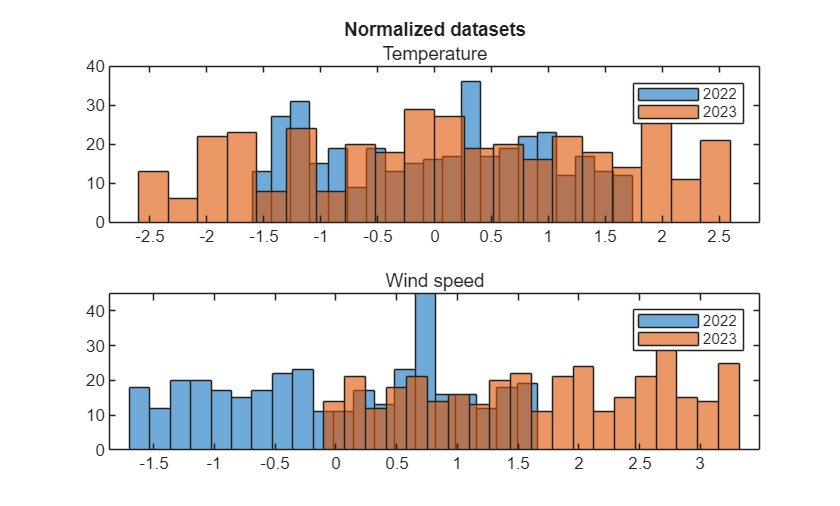

tiledlayout('flow');
nexttile;
histogram(NormData2022.Temperature, 20, DisplayName = '2022');
hold on
histogram(NormData2023.Temperature, 20, DisplayName = '2023');
hold off
legend
title('Normalized datasets');
subtitle('Temperature');

nexttile;   
histogram(NormData2022.WindSpeed, 20, DisplayName = '2022');
hold on
histogram(NormData2023.WindSpeed, 20, DisplayName = '2023');
hold off
legend
subtitle('Wind speed');